# Matrices and Arrays

All MATLAB variables are multidimensional *arrays*, no matter what type of data. A *matrix* is a two-dimensional array often used for linear algebra.

## Array Creation

To create an array with four elements in a single row, separate the elements with either a comma (`,`) or a space.

a = [1 2 3 4]

a =      1     2     3     4


This type of array is a *row vector*.

`M = magic``(`[`n`](https://www.mathworks.com/help/matlab/ref/magic.html?searchHighlight=magic&s_tid=srchtitle#d123e792193)`)` returns an `n`-by-`n` matrix constructed from the integers `1` through `n`2 with equal row and column sums. The order `n` must be a scalar greater than or equal to `3` in order to create a valid magic square.

M = magic(3)

To create a matrix that has multiple rows, separate the rows with semicolons.

a = [1 2 3; 4 5 6; 7 8 10]

a =      1     2     3
     4     5     6
     7     8    10


Another way to create a matrix is to use a function, such as `ones`, `zeros`, or `rand`. For example, create a 5-by-1 column vector of zeros.

z = zeros(5,1)

z =      0
     0
     0
     0
     0


k = ones(3,4)

k =      1     1     1     1
     1     1     1     1
     1     1     1     1


# Matrix and Array Operations

MATLAB allows you to process all of the values in a matrix using a single arithmetic operator or function.

a + 10

ans =     11    12    13
    14    15    16
    17    18    20


sin(a)

ans =     0.8415    0.9093    0.1411
   -0.7568   -0.9589   -0.2794
    0.6570    0.9894   -0.5440


To transpose a matrix, use a single quote (`'`):

a'

ans =      1     4     7
     2     5     8
     3     6    10


## Element-wise multiplication and matrix multiplication

### Element-wise multiplication 

To perform element-wise multiplication rather than matrix multiplication, use the `.*` operator:

p = a .* a

p =      1     4     9
    16    25    36
    49    64   100


3 .* a

ans =      3     6     9
    12    15    18
    21    24    30


*Multiply Two Arrays*

Create two 3-by-3 arrays, `A` and `B`, and multiply them element by element.

A = [1 0 3; 5 3 8; 2 4 6];
B = [2 3 7; 9 1 5; 8 8 3];
C = A.*B

C =      2     0    21
    45     3    40
    16    32    18


`C = times(`[`A`](https://www.mathworks.com/help/matlab/ref/times.html#btx_6a1-A)`,`[`B`](https://www.mathworks.com/help/matlab/ref/times.html#btx_6a1-A)`)` is an alternate way to execute `A.*B`, but is rarely used. It enables operator overloading for classes.

### **Matrix multiplication**

The matrix multiplication operator calculates the product of two matrices with the formula,

To see this, you can calculate the product of two matrices.

A = [1 3;2 4]

A =      1     3
     2     4


B = [3 0;1 5]

B =      3     0
     1     5


A*B

ans =      6    15
    10    20


The previous matrix product is not equal to the following element-wise product.

A.*B

ans =      3     0
     2    20


[`C`](https://www.mathworks.com/help/matlab/ref/mtimes.html#btx9i74-C) `= mtimes(`[`A`](https://www.mathworks.com/help/matlab/ref/mtimes.html#btx9i74-A)`,`[`B`](https://www.mathworks.com/help/matlab/ref/mtimes.html#btx9i74-A)`)` is an alternative way to execute `A*B`, but is rarely used. It enables operator overloading for classes.

**The following table provides a summary of elementary operations and matrix operations.**

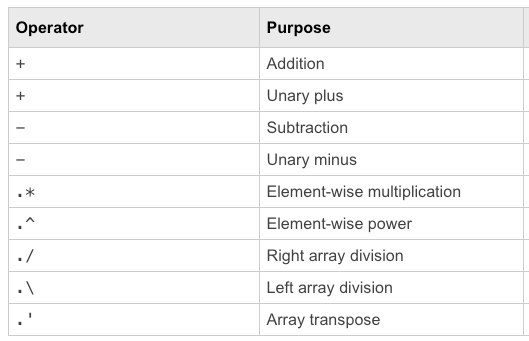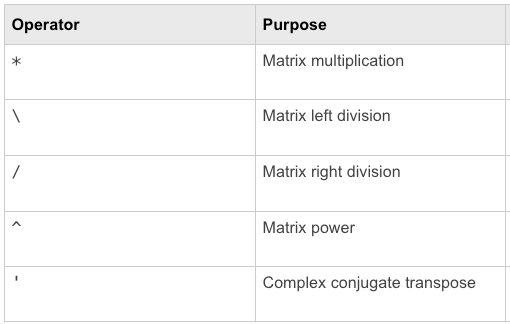

## Concatenation

*Concatenation* is the process of joining arrays to make larger ones. In fact, you made your first array by concatenating its individual elements. The pair of square brackets `[]` is the concatenation operator.

A = [a,a]

A =      1     2     3     1     2     3
     4     5     6     4     5     6
     7     8    10     7     8    10


Concatenating arrays next to one another using commas is called *horizontal* concatenation. Each array must have the same number of rows. Similarly, when the arrays have the same number of columns, you can concatenate *vertically* using semicolons.

A = [a; a]

A =      1     2     3
     4     5     6
     7     8    10
     1     2     3
     4     5     6
     7     8    10


#### Repeat copies of array

`B =` `repmat``(`[`A`](https://www.mathworks.com/help/matlab/ref/repmat.html?searchHighlight=repmat&s_tid=srchtitle#btzavfc-1-A)`,`[`n`](https://www.mathworks.com/help/matlab/ref/repmat.html?searchHighlight=repmat&s_tid=srchtitle#btzavfc-1-n)`)` returns an array containing `n` copies of `A` in the row and column dimensions. 

B = repmat(10,3,2)

B =     10    10
    10    10
    10    10


a = diag([100 200 300])

a =    100     0     0
     0   200     0
     0     0   300


A = repmat(a,2)

A =    100     0     0   100     0     0
     0   200     0     0   200     0
     0     0   300     0     0   300
   100     0     0   100     0     0
     0   200     0     0   200     0
     0     0   300     0     0   300


A = repmat(a,1,3)

A =    100     0     0   100     0     0   100     0     0
     0   200     0     0   200     0     0   200     0
     0     0   300     0     0   300     0     0   300


## Reshape

[`B`](https://www.mathworks.com/help/matlab/ref/reshape.html#bud6j0x-1-B) `= reshape(`[`A`](https://www.mathworks.com/help/matlab/ref/reshape.html#bud6j0x-1-A)`,`[`sz`](https://www.mathworks.com/help/matlab/ref/reshape.html#bud6j0x-1-sz)`)` reshapes `A` using the size vector, `sz`, to define `size(B)`. For example, `reshape(A,[2,3])` reshapes `A` into a 2-by-3 matrix. `sz` must contain at least 2 elements, and `prod(sz)` must be the same as `numel(A)`.

Reshape a 1-by-10 vector into a 5-by-2 matrix.

A = 1:10;
B = reshape(A,[5,2])

B =      1     6
     2     7
     3     8
     4     9
     5    10


Reshape a 4-by-4 square matrix into a matrix that has 2 columns. Specify `[]` for the first dimension to let `reshape` automatically calculate the appropriate number of rows.

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


B = reshape(A,[],2)

B =     16     3
     5    10
     9     6
     4    15
     2    13
    11     8
     7    12
    14     1


reshape(A',[],2)

ans =     16     9
     2     7
     3     6
    13    12
     5     4
    11    14
    10    15
     8     1


The result is an 8-by-2 matrix, which maintains the same number of elements as the original matrix. The elements in `B` also maintain their columnwise order from `A`.

Reshape a 3-by-2-by-3 array of zeros into a 9-by-2 matrix.

A = zeros(3,2,3);
B = reshape(A,9,2)

B =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


# Array Indexing

Every variable in MATLAB® is an array that can hold many numbers. When you want to access selected elements of an array, use indexing.

For example, consider the 4-by-4 magic square `A`:

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


There are two ways to refer to a particular element in an array. The most common way is to specify row and column subscripts, such as

A(4,2)

ans = 14

Less common, but sometimes useful, is to use a single subscript that traverses down each column in order:

A(8)

ans = 14

Using a single subscript to refer to a particular element in an array is called *linear indexing*.

If you try to refer to elements outside an array on the right side of an assignment statement, MATLAB throws an error.

`Index exceeds matrix dimensions.`

However, on the left side of an assignment statement, you can specify elements outside the current dimensions. The size of the array increases to accommodate the newcomers.

A(4,5) = 17

A =     16     2     3    13     0
     5    11    10     8     0
     9     7     6    12     0
     4    14    15     1    17


To refer to multiple elements of an array, use the colon operator, which allows you to specify a range of the form `start:end`. For example, list the elements in the first three rows and the second column of `A`:

A(1:3,2)

ans =      2
    11
     7


#### vectorization

The colon alone, without start or end values, specifies all of the elements in that dimension. For example, select all the columns in the third row of `A`:

A(3,:)

ans =      9     7     6    12     0


(:) makes A one column vector

A(:)

ans =     16
     5
     9
     4
     2
    11
     7
    14
     3
    10


#### spaced vector

The colon operator also allows you to create an equally spaced vector of values using the more general form `start:step:end`.

B = 0:10:100

B =      0    10    20    30    40    50    60    70    80    90   100


x = 5:-1:-5

x =      5     4     3     2     1     0    -1    -2    -3    -4    -5


If you omit the middle step, as in `start:end`, MATLAB uses the default step value of `1`.

`y = linspace``(`[`x1,x2`](https://www.mathworks.com/help/matlab/ref/linspace.html?searchHighlight=linspace&s_tid=srchtitle#bud27em-x1x2)`)` returns a row vector of 100 evenly spaced points between `x1` and `x2`.

`y =` `linspace``(`[`x1,x2`](https://www.mathworks.com/help/matlab/ref/linspace.html?searchHighlight=linspace&s_tid=srchtitle#bud27em-x1x2)`,`[`n`](https://www.mathworks.com/help/matlab/ref/linspace.html?searchHighlight=linspace&s_tid=srchtitle#bud27em-n)`)` generates `n` points. The spacing between the points is `(x2-x1)/(n-1)`.

`linspace` is similar to the colon operator, “`:`”, but gives direct control over the number of points and always includes the endpoints. “`lin`” in the name “`linspace`” refers to generating linearly spaced values as opposed to the sibling function `logspace`, which generates logarithmically spaced values.

Create a vector of 100 evenly spaced points in the interval `[-5,5]`.

y = linspace(-5,5)

y =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


Create a vector of 7 evenly spaced points in the interval `[-5,5]`.

y1 = linspace(-5,5,7)

y1 =    -5.0000   -3.3333   -1.6667         0    1.6667    3.3333    5.0000


Let create same vector with B using linspace

B1 = linspace(0,100,11)

B1 =      0    10    20    30    40    50    60    70    80    90   100


isequal(B, B1)  % Determine array equality

ans = logical
   1


B and B1 is same!